# Clear console and workspace and add project root to path

close all;
clearvars -except app;
project_root='/home/predator/swarmlab/';
addpath(genpath(project_root));

## Simulation options

DRONE_TYPE = "quadcopter"; % either fixed-wing, or quadcopter
DEBUG = true; % true to plot the state of the drone, false otherwise
VIDEO = false; % true to record a video, false otherwise
CENTER_VIEW_ON_DRONE = true; % true to center the drone in the viewer, false otherwise
WIND_ACTIVE = false; % true to activate steady wind, false otherwise
WIND_GUST_ACTIVE = false; % true to activate wind gusts, false otherwise

## Run parameters files

run('param_physics');
run('param_drone'); 
run('param_sim');
run('param_battery');
run('param_map');

## Initalize wind

wind_level = 0;
wind_gust_level = 0;
wind = zeros(6, 1); % steady wind (1:3), wind gusts (3:6)

## Initialize drone, video writer and drone viewer

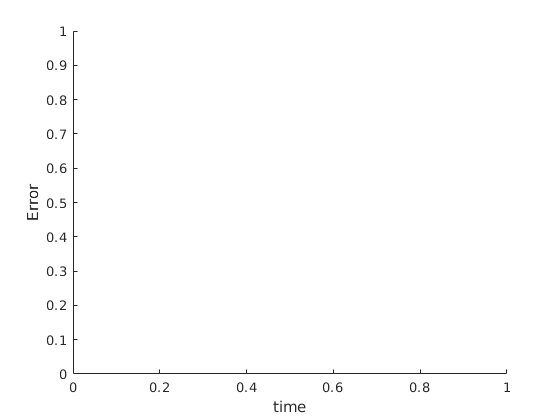

% Init drone
drone = Drone(DRONE_TYPE, p_drone, p_battery, p_sim, p_physics, map);
drone.set_pos([rand() * map.width; rand() * map.width; -rand() * map.max_height]);



xlabel("time");
ylabel("Error");

% Init drone viewer
drone_viewer = DroneViewer(drone, p_sim.dt_plot, CENTER_VIEW_ON_DRONE);
drone.set_pos([0 ; 0 ; 0]);
display(drone.pos_ned)

     0
     0
     0



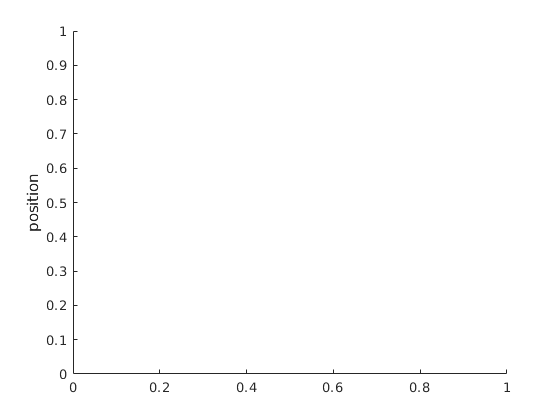


f1=figure;
h1=animatedline('Color','g');
ylabel("position");
hold on

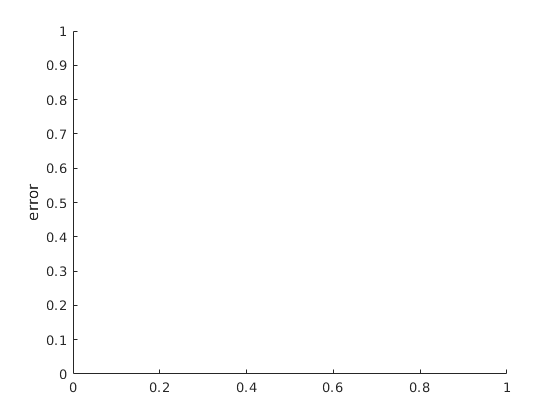

f2=figure;
h2=animatedline('Color','b');
h3=animatedline('Color','r');
h4=animatedline('Color','g');
ylabel("error");
hold on

## Main simulation loop

kp=[1,1,1];
ki=[0,0,0];
kd=[4,4,4];
vel=zeros(1,3);
error=zeros(1,3);
error_prev=zeros(1,3);
error_sum=zeros(1,3);
error_diff=zeros(1,3);
velsat=10;

disp('Type CTRL-C to exit');

Type CTRL-C to exit


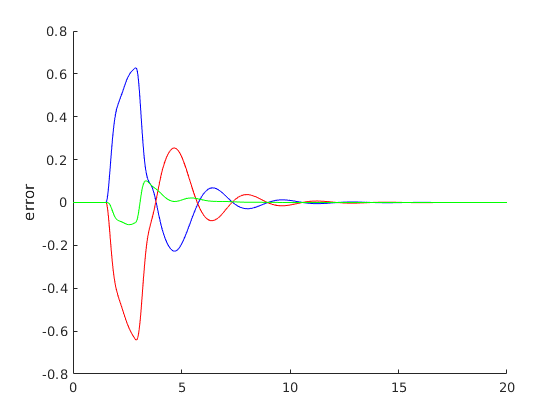


for time = p_sim.start_time:p_sim.dt:20
    
    error=[10 10 10]-drone.pos_ned';
    error_diff=error-error_prev;
    error_sum=error_sum+error;
    vel=kp.*error + ki.*error_sum + kd.*error_diff;
    error_prev=error;
    
    k=vel>velsat;
    vel(k)=velsat;
    k=vel<-velsat;
    vel(k)=-velsat;
    vel=-vel;

    drone.command = [0 -vel(1) -vel(2) -vel(3)];
    addpoints(h2,time,drone.attitude(1));
    addpoints(h3,time,drone.attitude(2));
    addpoints(h4,time,drone.attitude(3));

    drone.update_state(wind, time);
    hold on;
    

end


disp('Simulation completed successfully');

Simulation completed successfully
